% SHAPC-Mean and SHAPC-Var Comparison
algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", ...
     "der", "icarl", "ds-al", "tagfex", "xder"];
dataset = 'cifar100';

if dataset == "cifar100"
    num_sessions = 10;
    cls_per_task = 10;
else
    num_sessions = 5;
    cls_per_task = 2;
end

if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end
num_algs = length(algs);

file_path = sprintf("%s_all_inclass_shapcs.mat", dataset);
if isfile(file_path)
    all_inclass_shapcs = load(file_path).all_inclass_shapcs;
else
    all_inclass_shapcs = zeros(((num_sessions-1)*cls_per_task), num_algs+1);
end

for j=1:length(algs)
    alg = algs(j);
    % Load SHAPC values (First and Last 1000)
    save_path = sprintf("%s/%s/shapc_vals_inclass.mat", alg, dataset);
    if isfile(save_path)
        inclass_struct = load(save_path);
    
        for i=1:((num_sessions-1)*cls_per_task)
            cls = i - 1;
    
            cls_str = sprintf("cls%d", cls);
            shapc_struct = inclass_struct.(cls_str);
           
            % Load SHAPC values all
            shapc_avgs = [];
            pair_str = 'sc' + string(floor(cls/cls_per_task)) + string(num_sessions-1);
            shapcs = [];
            sample_list = string(fieldnames(shapc_struct.(pair_str)));
            for k=1:length(fieldnames(shapc_struct.(pair_str)))
                sample_str = sample_list(k);%'sample' + string(k-1);
                shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
            end
            shapc_avgs = [shapc_avgs; mean(shapcs)];
            
            % Note the shapc is represented as percentage
            %disp("From averaging all tasks together:")
            shapc_mean_perc = mean(shapc_avgs);
            shapc_mean = mean(shapc_avgs) / 100;
                        
            if ~exist('inclass_shapcs','var')
                inclass_shapcs = zeros(((num_sessions-1)*cls_per_task),2);
            end
            
            inclass_shapcs(cls+1,1) = cls;
            inclass_shapcs(cls+1,2) = shapc_mean_perc;
        end
        all_inclass_shapcs(:, find(algs==alg)+1) = inclass_shapcs(:,2);
    end
    save(file_path, "all_inclass_shapcs")
end

% Display All Results
fprintf('Inclass SHAPC-Mean Percentages:\n');

Inclass SHAPC-Mean Percentages:


disp(inclass_shapcs);

         0   31.3823
    1.0000   28.7898
    2.0000   27.7043
    3.0000   25.2465
    4.0000   25.8867
    5.0000   27.7571
    6.0000   30.3530
    7.0000   27.7007
    8.0000   29.8270
    9.0000   28.5318
   10.0000   26.3632
   11.0000   29.7512
   12.0000   28.4229
   13.0000   30.9839
   14.0000   28.1973
   15.0000   28.3027
   16.0000   28.6761
   17.0000   31.3173
   18.0000   27.2784
   19.0000   27.7268
   20.0000   34.5729
   21.0000   32.1997
   22.0000   29.7301
   23.0000   33.8519
   24.0000   30.5844
   25.0000   30.2638
   26.0000   29.8682
   27.0000   26.1334
   28.0000   31.2653
   29.0000   28.0759
   30.0000   31.3728
   31.0000   32.4514
   32.0000   29.0956
   33.0000   34.1347
   34.0000   31.3545
   35.0000   33.4875
   36.0000   34.1089
   37.0000   35.4360
   38.0000   29.7349
   39.0000   32.0173
   40.0000   31.9963
   41.0000   36.8303
   42.0000   32.3677
   43.0000   35.3263
   44.0000   29.2948
   45.0000   31.3735
   46.0000   34.6936
   47.0000   


fprintf('Std Dev:\n');

Std Dev:


disp(std(inclass_shapcs(:,2)))

    7.0348




fprintf('Avg:\n');

Avg:


disp(mean(inclass_shapcs(:,2)))

   35.6994



create_table = true;
if create_table
    if ~exist('inclass_shapcs','var')
        all_inclass_shapcs = load(file_path).all_inclass_shapcs;
    end

    % Create a table for better visualization of results
    all_inclass_shapcs(:, 1) = (1:(num_sessions-1)*cls_per_task)-1;
    resultsTable = array2table(all_inclass_shapcs, 'VariableNames', ['Class' algs]);
    disp(resultsTable);

    all_std_devs = [NaN std(all_inclass_shapcs(:, 2:end))];
    fprintf('Std Devs:\n');
    disp(all_std_devs);

    all_avgs = [NaN mean(all_inclass_shapcs(:, 2:end))];
    fprintf('Averages:\n');
    disp(all_avgs);
end

    Class    iTAML     RPSnet    foster     memo      der      icarl     ds-al    tagfex     xder 
    _____    ______    ______    ______    ______    ______    ______    _____    ______    ______

      0      23.953    27.571     26.88    25.802      32.7    25.229      0        0       31.382
      1      25.983    23.985    26.719    24.582    32.547    22.368      0        0        28.79
      2       24.27    24.637    25.505    23.566    28.301    24.013      0        0       27.704
      3      22.692    22.978    24.142    22.605    25.132    22.825      0        0       25.246
      4      23.086    22.528    26.404    23.009    24.692    22

Std Devs:


       NaN    2.8994    8.2129    2.8379    4.5576    8.3585    4.2690         0         0    7.0348



Averages:


       NaN   27.2600   30.7623   28.7740   31.2215   41.4523   27.2181         0         0   35.6994




% Cls 7 has the highest SHAPCs for all algs
% Except for foster -> Cls 8

% Cls 1 has the lowest SHAPCs for all algs
% Except for RPSnet -> Cls 4

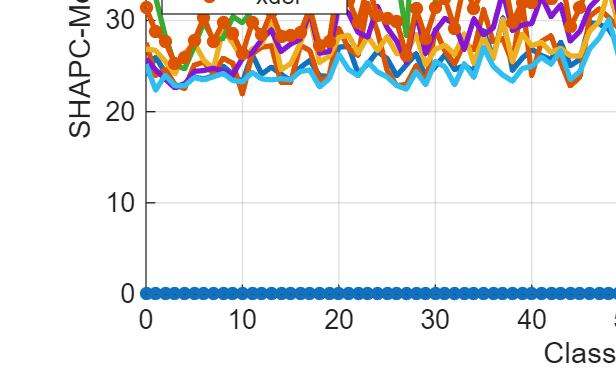

% Plot inclass shapcs

plot((all_inclass_shapcs(:, 1)), ...
    (all_inclass_shapcs(:, 2:end)), ...
    'LineWidth', 2, 'MarkerSize', 3)
linestyles = ["-", "-", "-", "-", "-", "-", "-", "-o", "-o"];
linestyleorder(linestyles)
title('Classwise SHAPC-Means for All Algorithms');
xlabel('Class');
ylabel('SHAPC-Mean (%)');
legend(algs,"Location", "best")
grid on;